# Estimate a discrete-time transfer function from a step response

## Reading the recorded data

We first need to define the input data files. The first file mentioned in the code below containts data that was recorded for a fixed, not moving sensor ('calibration data'). This data is required, because the gyrometer data has a steady state error. We need to determine the steady state error for all gyrometers and subtract it from the data measured in the step response experiments. 

The second filename below belongs to the file with the actual step response experiment data. The step response data was recorded for a step of 5 degrees. This value is fixed in the microcontroller code for the step response experiment, and it needs to be set here by hand. 

TODO: Teach arduino code to export uStep. 

clear all;
close all; 
filename_calibration_data= "calibration-2022-01-01.txt";
filename_step_response_data= "step_responses_20deg-2022-01-01b.txt"; 
uStep= 5; % deg, degrees
calibration_data= readtable(filename_calibration_data);
yCali= calibration_data{:, 3};
y0= sum(yCali(:))/length(yCali); % offset of yGyro raw data

Similarly, the rough time start point and end point of the step response need to be set by hand (by visual inspeciton). We discard all data before and after these times.

TODO: Teach arduino to export time of step response. 

ktstart= 660; 
ktstop= 800;
data = readtable(filename_step_response_data); 
tData = data{ktstart:ktstop, 1}'; % note transpose operator
yData = data{ktstart:ktstop, 3}';
t0= tData(1);
numpoints= length(yData);

We can now subtract the constant gyrometer offsets from the data and divide all time data by 1e6 to correctly account for microseconds. 

yData = yData - ones(1, numpoints) * y0;
tData= tData- ones(1, numpoints) * t0; 
tData= tData* 1e-6; 

We can now select the time point at which the step occurs more precisely in the remaining data (by visual inspection again, not done here). The input signal is then reconstructed accordingly. 

ktStep= 11; % 
uData= uStep* ones(1, numpoints); 
uData(1:ktStep-1)= zeros(1, ktStep-1);

Data is assumed to be recorded with the sensor set at a resolution of +/-1000 degrees per seconds (dps). The sensor raw data needs to be converted to this range. This is done by calling the function mapGyroData1000dps, which is defined further below. The information required to program this function is taken from the sensor datasheet.  

yDataDegPerSecond = zeros(1, numpoints); 
for k = 1:numpoints
    yDataDegPerSecond(k)= mapGyroData1000dps(yData(k));
end

Furthermore, it assumed the data was recorded with a sampling time of 5ms. 

delta_t = 0.005; %  seconds

We are now ready to plot the recorded data. The gyroscopes measure angular velocity. We need to integrate the velocities (in degrees per secods, dps) to obtain the angle(in degrees) by which the gyrometer (and the camera attached to it) moved. The integration is merely a summation. It is implemented in the function integrate, which is defined further below.

figCounter= 1; 
figTitle= "integrated (summed) gyro signal in deg, step count on x-axis"; 
figure(figCounter);
title(figTitle); 

hold on;
yDeg= integrate(yDataDegPerSecond, delta_t); 
plot(yDeg, '-*', 'Color', 'black'); 
plot(uData);
legend('y', 'u'); 
xlabel('step');
ylabel('phi in deg');
hold off; 

figCounter= figCounter+ 1; 
figTitle= "integrated gyro signal in deg, time in seconds on x-axis"; 
figure(figCounter);
title(figTitle);
hold on;
plot(tData, yDeg, '-*', 'Color', 'black'); 
plot(tData, uData); 
legend('y', 'u'); 
xlabel('t in seconds');
ylabel('phi in deg');
hold off; 

## Identification 

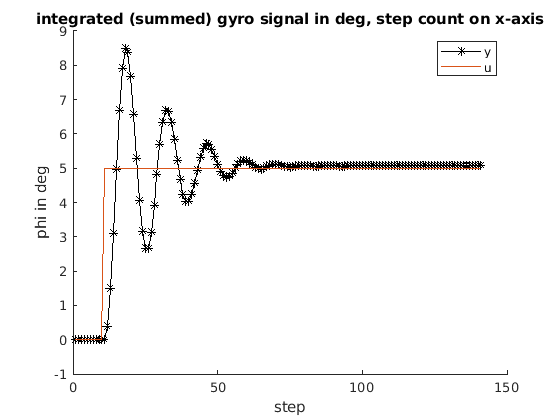

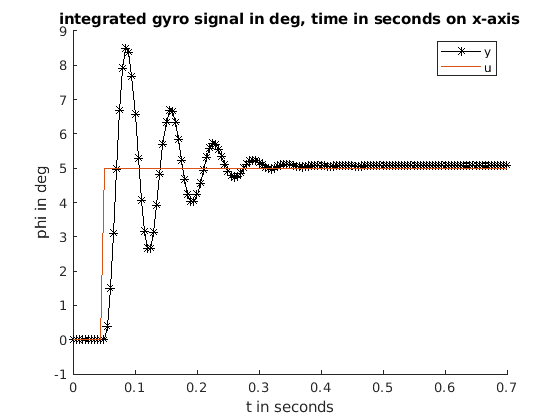

identData= iddata(yDeg', uData', delta_t); 
continuousTimeTransferFunction= tfest(identData, 2, 0);  

[ySim, tSim, xSim]= step(continuousTimeTransferFunction, tData(end)); 

figCounter= figCounter+ 1; 
figTitle= "state space model, \phi and integrated \omega";
figure(figCounter);
title(figTitle);
hold on; 
plot(tSim, ySim* uStep);

Let's plot the open-loop step response also by simulating the state space model. There is a built-in matlab command (tf2ss) that converts the transfer function into a state-space model. Here, we carry out this transformation by hand, because it is instructive. Moreover, the conversion does not yield a unique result and, therefore, we have better control over the transformation, if we carry it out by hand:

The transfer function has the form

 
$$\[
G(s)= \frac{K_S}{s^2+ a_1 s+ a_0}
\]$$


and, according to the course notes, this transfer function can be transformed into the state-space model


$$\pmatrix{\dot\varphi \cr \dot\omega}=
\pmatrix{0 & 1 \cr -a_0 & -a_1} \pmatrix{\varphi \cr \omega}+
\pmatrix{0 \cr K_S} u, \quad
y= (1\, 0)\pmatrix{\varphi \cr \omega}
$$


with state vector $x= \pmatrix{\varphi \cr \omega}$. The matrices $A, B, C, D$ for the standard notation

$\dot x= Ax+ Bu, \quad y=Cx+Du
$ are introduced in the next code section:

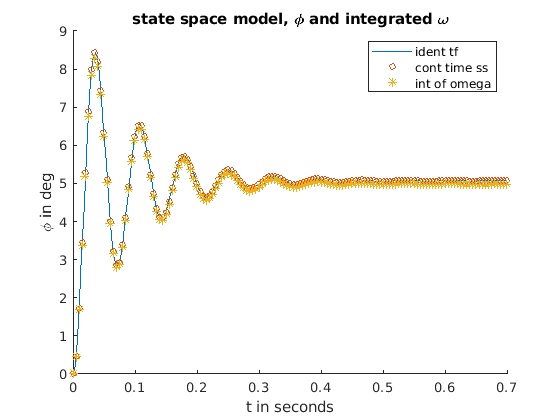

a1= continuousTimeTransferFunction.denom(2);
a0= continuousTimeTransferFunction.denom(3);
KS= continuousTimeTransferFunction.numer(1);
continuousTimeStateSpaceSys.A= [0 1; -a0 -a1];
continuousTimeStateSpaceSys.B= [0; KS];
continuousTimeStateSpaceSys.C= [1 0];
continuousTimeStateSpaceSys.D= 0; 
%[A, B, C, D]= tf2ss(sys.num, sys.denom);
tGridTmp= 0:delta_t:tSim(end);
uStepTimeSeriesTmp= uStep* ones(length(tGridTmp), 1);
[angleOut, tOutTmp, xOutTmp]= lsim(ss(continuousTimeStateSpaceSys.A, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D), uStepTimeSeriesTmp, tGridTmp, [0 0]);

plot(tOutTmp, angleOut, "o", 'MarkerSize', 5); 
xlabel('t in seconds');
ylabel('\phi in deg'); 
% figure();
% plot(tOutTmp, xOutTmp(:,2));
phiFromOmega= zeros(length(tOutTmp), 1);
for k= 2:length(tOutTmp)
    phiFromOmega(k)= phiFromOmega(k-1)+ 0.5*(xOutTmp(k-1, 2)+ xOutTmp(k, 2))* (tOutTmp(k)- tOutTmp(k-1)); 
end
plot(tOutTmp, phiFromOmega, '*'); 
legend('ident tf', 'cont time ss', 'int of omega')
hold off;

Finally, let's compare the model and the experimental data.

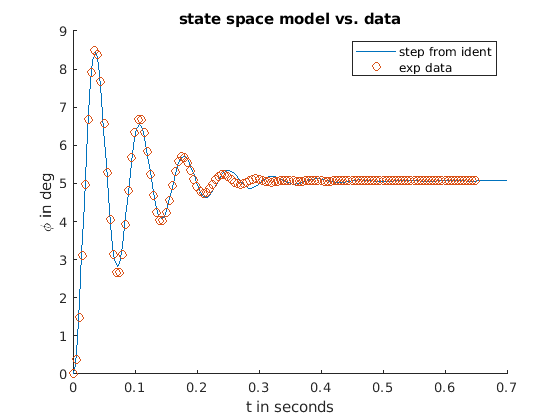

figCounter= figCounter+ 1; 
figTitle= "state space model vs. data";
figure(figCounter);
title(figTitle);
hold on; 
plot(tSim, ySim* uStep);
shifted_tData= tData(ktStep:end)- tData(ktStep);
shifted_yDeg= yDeg(ktStep:end);
plot(shifted_tData, shifted_yDeg, 'o');
xlabel('t in seconds');
ylabel('\phi in deg'); 
legend('step from ident', 'exp data');
hold off; 

## Let's also plot omega for later use (comparison to discrete-time results)

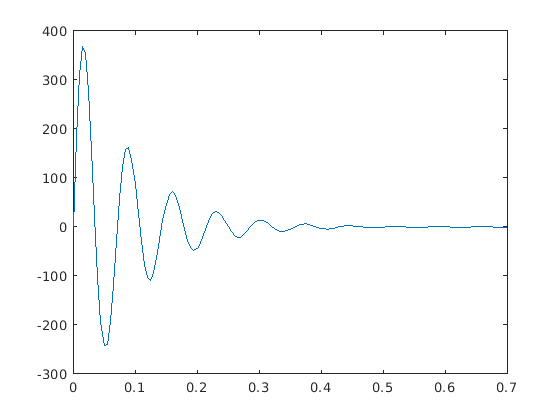

figCounter= figCounter+ 1;
figure(figCounter);
plot(tOutTmp, xOutTmp(:,2));

## Pole placement for state feedback 

K= place(continuousTimeStateSpaceSys.A, continuousTimeStateSpaceSys.B, [-11 -10]);

We cannot yet implement this state feedback, since we only measure one of the two states (the angular velocity, but not the angle itself). We need to design an observer below to determine the missing angle information. Before we do so, let us assume we could implement the controller and check what a step response of the closed-loop system for a 5 degree input step would look like.

% determine closed-loop transfer function (input reference value for angle,
% output actual angle)
[NumerClosed, DenomClosed]= ss2tf(continuousTimeStateSpaceSys.A-continuousTimeStateSpaceSys.B*K, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D);
Gclosed= tf(NumerClosed, DenomClosed);

%
% plot closed-loop step response with prefactor
%
figCounter= figCounter+ 1; 
figTitle= "step response, with state feedback, time in seconds";
figure(figCounter);
title(figTitle);
hold on; 
[ySimClosed, tSimClosed]= step(Gclosed);
Bref= 1/ ySimClosed(end); % input matrix (1x1 matrix here) for scaling the reference input
plot(tSimClosed, ySimClosed*Bref*uStep); % instead of multiplying step by Bref we can multiply output, since the system is linear

Just to be safe, let's compare the last result to the result computed with the time-domain system.

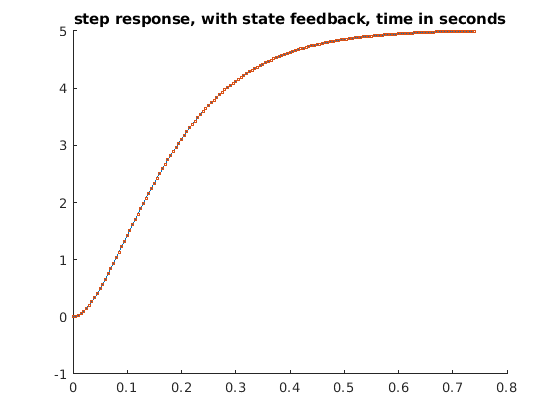

tGridTmp= 0:delta_t:tSimClosed(end); 
uStepTimeSeriesTmp= uStep* Bref* ones(length(tGridTmp), 1);
[angleOut, tOutTmp]= lsim(ss(continuousTimeStateSpaceSys.A-continuousTimeStateSpaceSys.B*K, continuousTimeStateSpaceSys.B, continuousTimeStateSpaceSys.C, continuousTimeStateSpaceSys.D), uStepTimeSeriesTmp, tGridTmp, [0 0]);
plot(tOutTmp, angleOut, "o", 'MarkerSize', 2); 
hold off; 

## State feedback with observer, continuous time, perfect model

Since we cannot measure both states, but only the angular velocity, we have to design an observer in order to be able to use the state feedback. 

Note that our model has the angle as its output. In order to design an observer for the angular velocity, we have to change the output matrix C so as to turn the angular velocity into the output.

Ltransposed= place(continuousTimeStateSpaceSys.A', continuousTimeStateSpaceSys.C', [-101 -100]);
L= Ltransposed'; 

It is convenient to define a system that contains both the simulated system and the observer. This can be done as follows.

Asim = [ continuousTimeStateSpaceSys.A- continuousTimeStateSpaceSys.B* K             continuousTimeStateSpaceSys.B* K
         zeros(size(continuousTimeStateSpaceSys.A))    continuousTimeStateSpaceSys.A- L* continuousTimeStateSpaceSys.C ];

Bsim = [    continuousTimeStateSpaceSys.B* Bref
            zeros(size(continuousTimeStateSpaceSys.B)) ];

Csim = [ continuousTimeStateSpaceSys.C, zeros(size(continuousTimeStateSpaceSys.C)) ];

simSys= ss(Asim, Bsim, Csim, 0);
tSim0= 0:delta_t:1;
uSim0= uStep* ones(size(tSim0));

We need to set the initial conditions and then can run the simulation.

phi0= 20; %deg
omega0= 0; %dps
phiHat0= 0;
omegaHat0= 0;
errPhi0= phi0- phiHat0;
errOmega0= omega0- omegaHat0;
[ySim, tSim, xSim]= lsim(simSys, uSim0, tSim0, [phi0 omega0 errPhi0 errOmega0]); 

Remember states 3 and 4 are the errors e, where e= x- xhat and xhat are the states of the estimator.

errorSim= xSim(:,3:4);
xhatSim= xSim(:,1:2)- errorSim(:,:);

Plot angular velocities, simulated and observed. 

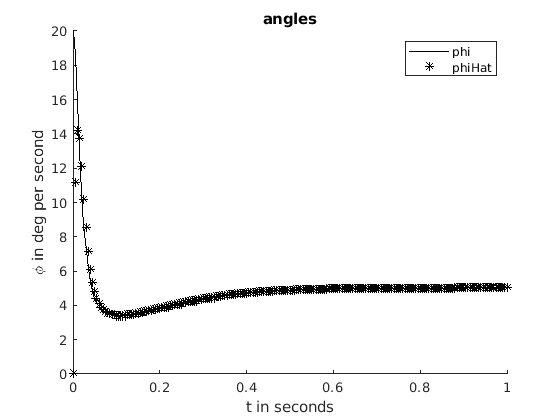

figCounter= figCounter+ 1;
figTitle= "angles";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim, xSim(:, 1), "Color", "black");
plot(tSim, xhatSim(:, 1), "*", "Color", "black");
legend('phi', 'phiHat');
xlabel('t in seconds');
ylabel('\phi in deg per second');
hold off; 

Plot angles, simulated and observed.

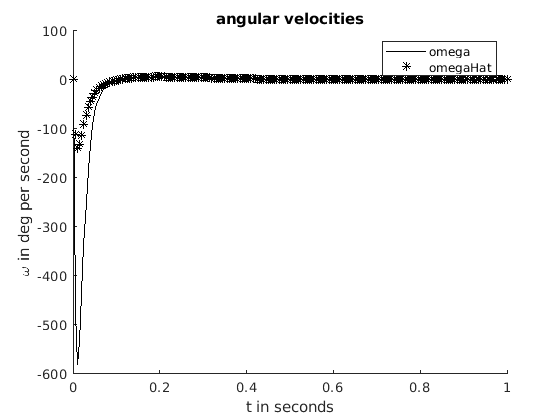

figCounter= figCounter+ 1;
figTitle= "angular velocities";
figure(figCounter);
title(figTitle);
hold on;
plot(tSim, xSim(:, 2), "Color", "black");
plot(tSim, xhatSim(:, 2), "*", "Color", "black");
xlabel('t in seconds');
ylabel('\omega in deg per second');
legend('omega', 'omegaHat')
hold off; 

## Export results to files, for use with other live scripts

identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction= continuousTimeTransferFunction;
identifyTransferFunctionContinuousTimeResults.continuousTimeStateSpaceSys= continuousTimeStateSpaceSys;
identifyTransferFunctionContinuousTimeResults.delta_t= delta_t;
identifyTransferFunctionContinuousTimeResults.uStep= uStep;
identifyTransferFunctionContinuousTimeResults.shifted_tData= shifted_tData;
identifyTransferFunctionContinuousTimeResults.shifted_yDeg= shifted_yDeg;
save("identifyTransferFunctionContinuousTimeResults.mat", 'identifyTransferFunctionContinuousTimeResults');

## Export matrices of the continuous-time state space system for use in Maple

Remember A and B suffice, since C and D are the same for the continuous-time and the corresponding discrete-time system. 

A= continuousTimeStateSpaceSys.A; % saveas command does not accept struct elements
B= continuousTimeStateSpaceSys.B;
C= continuousTimeStateSpaceSys.C;
D= continuousTimeStateSpaceSys.D;
save('matlabToMaple/A.txt', 'A', '-ascii');
save('matlabToMaple/B.txt', 'B', '-ascii');
save('matlabToMaple/C.txt', 'C', '-ascii');
save('matlabToMaple/D.txt', 'D', '-ascii');
save('matlabToMaple/delta_t.txt', 'delta_t', '-ascii');

## Auxiliary functions

Functions defined here at the end of the live-script can be called in the live-script above.

function res = mapGyroData1000dps(x)
    %MAPGYRODATA1000DPS Maps gyroscope raw data to deg/s.
    % Raw data is in range [-32768, 32767] and to be interpreted in
    % range [-1000, 1000] deg/s.
    a = 1000.0/32767;
    
    res= a* x; 
end

function res = integrate(signal, delta_t)
    %INTEGRATE Integrates signal once.
    
    % check for silly mistakes
    if size(signal, 1) ~= 1
        error('expecting leading dim 1');
    end

    num_points = length(signal);

    % allocate mem for result
    res = zeros(1, num_points);

    res(1) = 0; 
    for k = 2:num_points
        res(k)= res(k- 1)+ delta_t* signal(k); 
    end

end